# Assess Regression Neural Network Performance

Create a feedforward regression neural network (NN) model with fully connected layers using `fitrnet`. Use validation data for early stopping of the training process to prevent overfitting the model. Then, use the object functions of the model to assess its performance on test data.

clc;
clear all;
close all;

%running the simulation parameters
Parameters

#### Load Sample Data

Load the dataset compiled in the `dataset.mlx `file. The Dataset file is accesible in the [IEEEDataPort repository at this link](https://dx.doi.org/10.21227/vv2r-qn28) after loggin or in the [Ocean Code portal (dataset folder) at this link](https://codeocean.com/capsule/6777864/tree/v1) `(withouth any loggin requirements).` You need to download the dataset first and place on this local folder.

load Dataset_cell2cell.mat

Regenerate the dataset in case parameters have changed in the `Parameters.mlx` file

%Dataset_compiler

Delete posible rows of the table in which the table has missing values.

Dataset = rmmissing(Dataset);

#### Feature extraction

%Read the true distance among the cells
dist=table2array(Dataset(:,1));
%Read the vesicles released by the immune cell
sequence=table2array(Dataset(:,2:end));
%calculating the slope
window=2;
slope=sequence(:,window:end)-sequence(:,1:end-window+1);
%calculating the amplitude and location of peaks
[peak,loc]=min(slope,[],2);
%Conforming the new database
Dataset=array2table(horzcat(dist,peak,loc));

#### Plotting

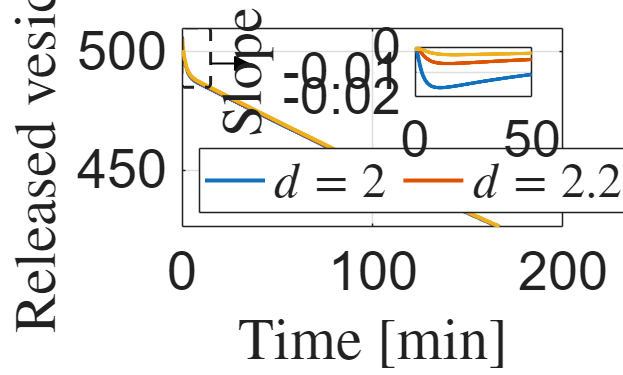

figure;
time=(0:length(sequence(1,:))-1)*dt0;
idx=1:20:50;
for i=idx
    plot(time/60,sequence(i,1:end),'LineWidth',2); grid on; hold on
end
xlabel('Time [min]','FontSize',fontsize,'Interpreter','latex');
ylabel({'Released vesicles'},'FontSize',fontsize,'Interpreter','latex');

legend({strcat('$d=',num2str(dist(idx(1))*10^6),'$'),...
        strcat('$d=',num2str(dist(idx(2))*10^6),'$'),...
        strcat('$d=',num2str(dist(idx(3))*10^6),'~\mu$m')},...
        'Interpreter','latex','Location','southwest','NumColumns',3);

set(gca,'FontSize',fontsize);
%Annotations
rectangle('Position',[0 485 15 25],'LineStyle','--','Curvature',0.2,'LineWidth',1.5); hold on;
h=annotation('arrow');

%Embedded plot
set(h,'parent', gca, ...
    'position', [15 495 20 0], ...
    'HeadLength', 7, 'HeadWidth', 7, 'HeadStyle', 'plain', ...
    'Color', 'k', 'LineWidth', 1);
p = get(gca, 'Position');
h_2 = axes('Parent', gcf, 'Position', [p(1)+0.45 p(2)+0.45 p(3)-0.5 p(4)-0.5]);
total=500;
for i=ceil(linspace(1,length(dist),3))
    plot(time(1:total),(slope(i,1:total)),'LineWidth',2); grid on; hold on
end
% xlabel('Time [s]','FontSize',fontsize,'Interpreter','latex');
ylabel({'Slope'},'FontSize',fontsize,'Interpreter','latex');
set(h_2,'FontSize',fontsize-1);

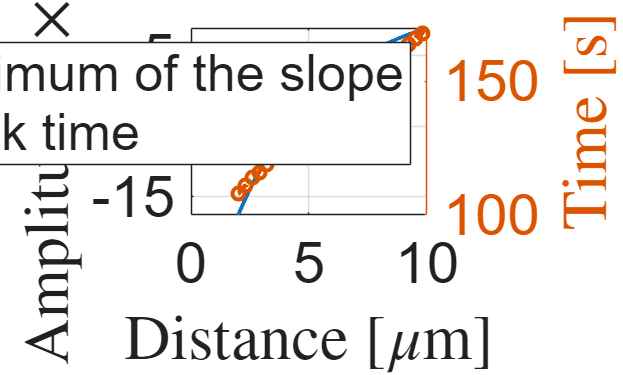


figure
plot(dist*1e6,peak*10^3,'LineWidth',2); grid on;
xlabel('Distance [$\mu$m]','Interpreter','latex');
ylabel('Amplitude [$\times 10^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize+2);

yyaxis right
plot(dist*1e6,loc,'--o','LineWidth',2,'MarkerIndices',1:30:length(loc)); grid on;
ylabel('Time [s]','Interpreter','latex');
set(gca,'FontSize',fontsize+2);

legend({'Minimum of the slope','Peak time'});

## Partition Data

Split the data into training, validation, and test sets. First, reserve approximately one tenth of the observations for the test set. Then, split the remaining data in one tenth to create the validation and training sets.

rng("default") % For reproducibility of the data partitions
%Test dataset
cvp1 = cvpartition(size(Dataset,1),"Holdout",1/10);
testTbl = Dataset(test(cvp1),:);
%Validation dataset
remainingTbl = Dataset(training(cvp1),:);
cvp2 = cvpartition(size(remainingTbl,1),"Holdout",(3/10/(1-1/10)));
validationTbl = remainingTbl(test(cvp2),:);
%Train dataset
trainTbl = remainingTbl(training(cvp2),:);

## Train Neural Network

Train a regression neural network model by using the training set. Specify the `Var1` column of `tblTrain` as the response variable, and standardize the numeric predictors. Evaluate the model at each iteration by using the validation set. Specify to display the training information at each iteration by using the `Verbose` name-value argument. By default, the training process ends early if the validation loss is greater than or equal to the minimum validation loss computed so far, six times in a row. To change the number of times the validation loss is allowed to be greater than or equal to the minimum, specify the `ValidationPatience` name-value argument.

Mdl = fitrnet(trainTbl,"Var1","Standardize",true, ...
    "ValidationData",validationTbl, 'ValidationPatience',10,...
    "Verbose",1,...
    "LayerSizes",[2],...
    "Activations",'sigmoid','LossTolerance',1e-9);

|==========================================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  | Validation | Validation |
|            |            |            |            | Time (sec) | Loss       | Checks     |
|==========================================================================================|
|           1|    0.012043|    0.218233|    0.252241|    0.183035|    0.011937|           0|
|           2|    0.000325|    0.004363|    0.087316|    0.016319|    0.000337|           0|
|           3|    0.000299|    0.004758|    0.004193|    0.024834|    0.000314|           0|
|           4|    0.000169|    0.003115|    0.040902|    0.007867|    0.000184|           0|
|           5|    0.000157|    0.001291|    0.009061|    0.017458|    0.000168|           0|
|           6|    0.000150|    0.002356|    0.010411|    0.003002|    0.000157|           0|
|           7|    0.000142|    0.004091|    0.012697|    0.001295|    

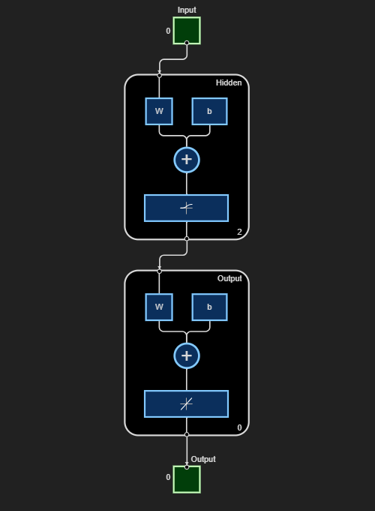

% Visualize the network structure
net=fitnet(Mdl.LayerSizes);
net.layers{1}.transferFcn='logsig';%corresponding to sigmoid within the Mdl object
view(net);

%net.numWeightElements

Use the information inside the `TrainingHistory` property of the object `Mdl` to check the iteration that corresponds to the minimum validation mean squared error (MSE). The final returned model `Mdl` is the model trained at this iteration.

iteration = Mdl.TrainingHistory.Iteration;
valLosses = Mdl.TrainingHistory.ValidationLoss;
[~,minIdx] = min(valLosses);
iteration(minIdx)

ans = 15

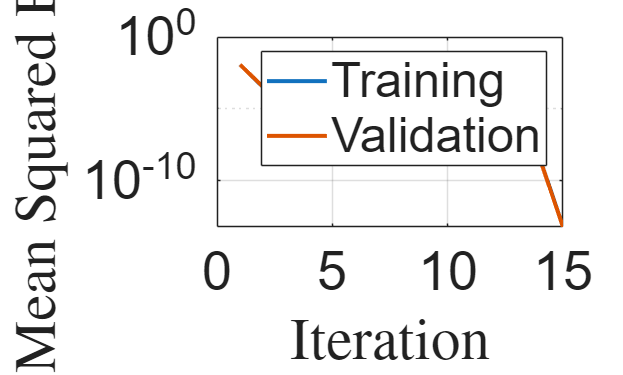

trainLosses = Mdl.TrainingHistory.TrainingLoss;

figure;
fontsize=27;
semilogy(iteration,trainLosses,iteration,valLosses,'LineWidth',2); grid on;
legend(["Training","Validation"])
xlabel("Iteration",'Interpreter','latex');
ylabel("Mean Squared Error",'Interpreter','latex');
set(gca,'FontSize',fontsize);

## Evaluate Test Set Performance

Evaluate the performance of the trained model `Mdl` on the test set `testTbl` by using the `loss` and `predict` object functions.

Compute the test set mean squared error (MSE). Smaller MSE values indicate better performance.

mse = loss(Mdl,testTbl,"Var1")

mse = 4.9745e-14

Compare the predicted test set response values to the true response values. Plot the predicted distances along the vertical axis and the true distance along the horizontal axis. Points on the reference line indicate correct predictions. A good model produces predictions that are scattered near the line.

predictedY = predict(Mdl,testTbl);

disp(['RMSE = ',num2str(rmse(predictedY,testTbl.Var1))])

RMSE = 2.2303e-07


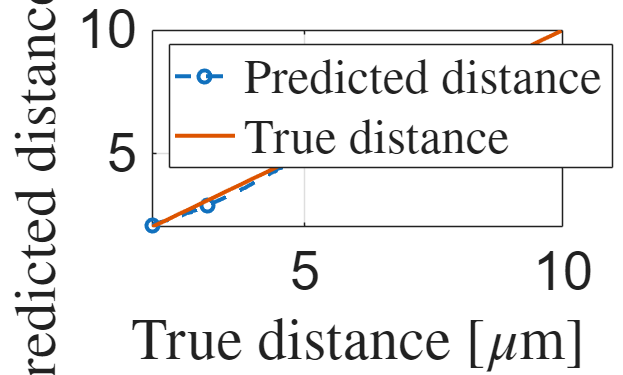


figure;
plot(testTbl.Var1*10^6,predictedY*10^6,"--o",'LineWidth',2,'MarkerIndices',1:20:length(dist));
grid on
hold on
plot(testTbl.Var1*10^6,testTbl.Var1*10^6,'LineWidth',2,'MarkerIndices',1:20:length(dist));
hold off

xlabel('True distance [$\mu$m]','Interpreter','latex');
ylabel('Predicted distance [$\mu$m]','Interpreter','latex');
legend({'Predicted distance','True distance'},'Interpreter','latex','Location','northwest');
set(gca,'FontSize',fontsize);